% Initialize values
clear;clc;
TR = 50;
T1 = 1000;
T2_dephasing = 50;
n=6;
Alpha = linspace(pi/12,pi/2,n);

% Iteration: N times of RF
N = 10;
% Mz
M_decade = ones(N,n);
M_recovery=[];
Mz=ones(1,n);
% Mxy
Mxy_decade = [];
Mxy_recovery=zeros(N,n);
Mxy=zeros(1,n);
for i=1:N
    % Excitation
    if i>1
        %M_decade(i,:) = Mz(end,:).*((1-exp(-TR/T1)).*sin(Alpha))./(1-exp(-TR/T1).*cos(Alpha)); 
        M_decade(i,:) = Mz(end,:).*cos(Alpha); 
        Mxy_recovery(i,:) = Mz(end,:).*sin(Alpha);
    else
        %M_decade(i,:) = ones(1,n).*((1-exp(-TR/T1)).*sin(Alpha))./(1-exp(-TR/T1).*cos(Alpha));
        M_decade(i,:) = ones(1,n).*cos(Alpha);
        Mxy_recovery(i,:) = ones(1,n).*sin(Alpha);
    end
    Mz = [Mz; M_decade(i,:)];
    Mxy = [Mxy; Mxy_recovery(i,:)];
    
    % Relaxation
    for j=2:TR
        M_recovery = [M_recovery;1+(M_decade(i,:)-1).*exp(-(j)/T1)];
        Mz = [Mz; M_recovery(end,:)];
        Mxy_decade = [Mxy_decade; Mxy_recovery(i,:).*exp(-(j)/T2_dephasing)];
        Mxy = [Mxy; Mxy_decade(end,:)];
    end
    
end

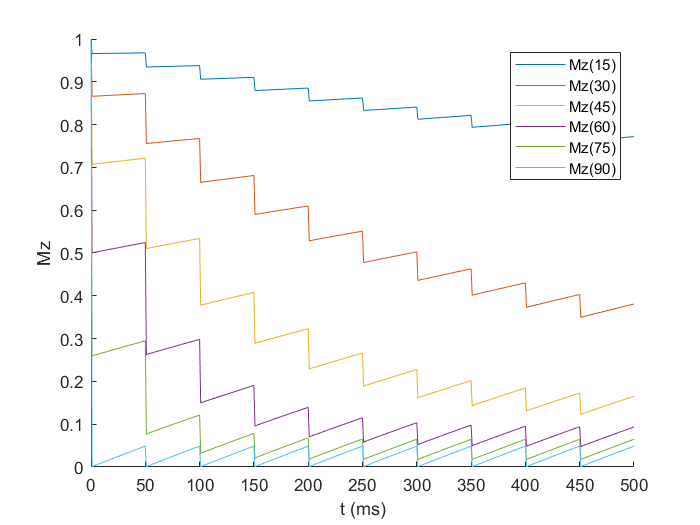

% Plot Mz
T = 0:TR*N;
figure();
hold on;
for i=1:n
    plot(T,Mz(:,i));
end
LineName = ['Mz(15)';'Mz(30)';'Mz(45)';'Mz(60)';'Mz(75)';'Mz(90)'] ;
legend(LineName);
axis([min(T(:)) max(T(:)) 0 1]);
ylabel('Mz'); xlabel('t (ms)')

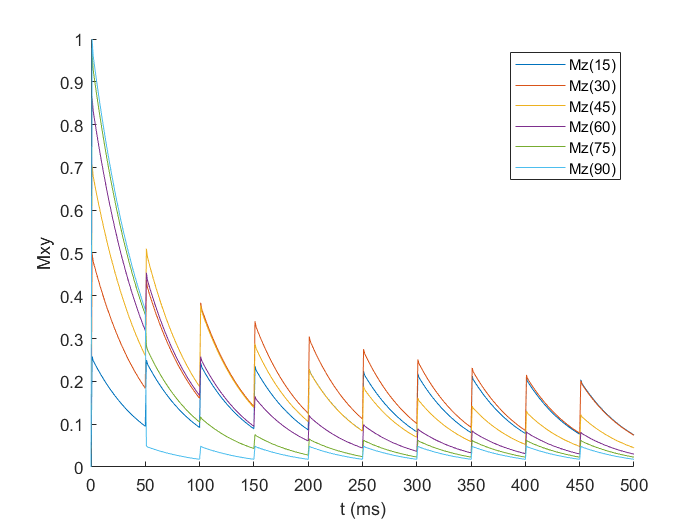

% Plot Mxy
T = 0:TR*N;
figure();
hold on;
for i=1:n
    plot(T,Mxy(:,i));
end
LineName = ['Mz(15)';'Mz(30)';'Mz(45)';'Mz(60)';'Mz(75)';'Mz(90)'] ;
legend(LineName);
axis([min(T(:)) max(T(:)) 0 1]);
ylabel('Mxy'); xlabel('t (ms)')